## Assignment 1 Part 1

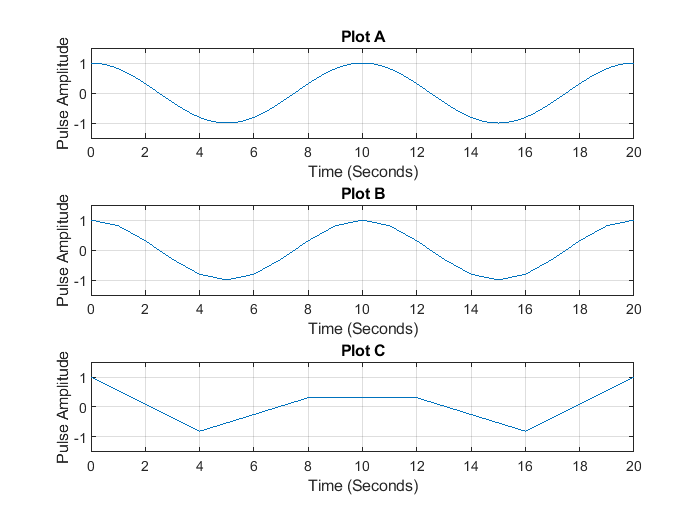

% Creating Three Cosine Functions
t1 = 0:0.1:20;  % Creating X-axis Time Vector
CosFunc1 = cos(2*pi*0.1*t1);

t2 = 0:1:20;  % Creating X-axis Time Vector
CosFunc2 = cos(2*pi*0.1*t2);

t3 = 0:4:20;  % Creating X-axis Time Vector
CosFunc3 = cos(2*pi*0.1*t3);

% Plotting Each Function
figure(1);
subplot(3,1,1);
plot(t1,CosFunc1);      %Plotting Cos1 Function
grid;
xlabel('Time (Seconds)')
ylabel('Pulse Amplitude')
title ('Plot A')
ylim([-1.5 1.5])

subplot(3,1,2);
plot(t2,CosFunc2);      %Plotting Cos2 Function
grid;
xlabel('Time (Seconds)')
ylabel('Pulse Amplitude')
title ('Plot B')
ylim([-1.5 1.5])

subplot(3,1,3);
plot(t3,CosFunc3);      %Plotting Cos3 Function
grid;
xlabel('Time (Seconds)')
ylabel('Pulse Amplitude')
title ('Plot C')
ylim([-1.5 1.5])

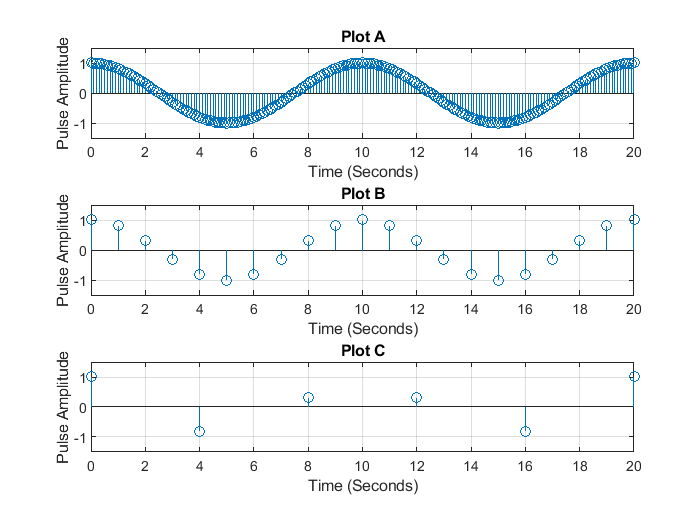


% STEM PLOTTING
figure(2);
subplot(3,1,1);
stem(t1,CosFunc1);
grid;
xlabel('Time (Seconds)')
ylabel('Pulse Amplitude')
title ('Plot A')
ylim([-1.5 1.5])

subplot(3,1,2);
stem(t2,CosFunc2);
grid;
xlabel('Time (Seconds)')
ylabel('Pulse Amplitude')
title ('Plot B')
ylim([-1.5 1.5])

subplot(3,1,3);
stem(t3,CosFunc3);
grid;
xlabel('Time (Seconds)')
ylabel('Pulse Amplitude')
title ('Plot C')
ylim([-1.5 1.5])

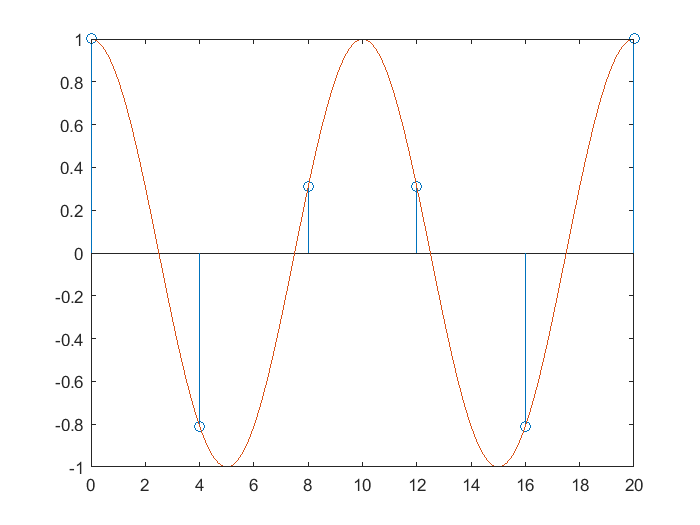

figure(3); %opens a new figure with handle#3
f1 = 0.1; %.1 Hz frequency for oversampled DT signal
f2 = 0.1; %.1 Hz frequency for “CT” signal
 %calculate the sampled DT signal
t1 = 0:4:20; %5 samples over 20 seconds
y1 = cos(2*pi*f1*t1);
%calculate the oversampled signal (CT)
t2 = 0:0.1:20; %200 samples over 20 seconds
y2 = cos(2*pi*f2*t2);
%compare DT to CT
stem(t1, y1);
hold on;
plot(t2, y2);
hold off;

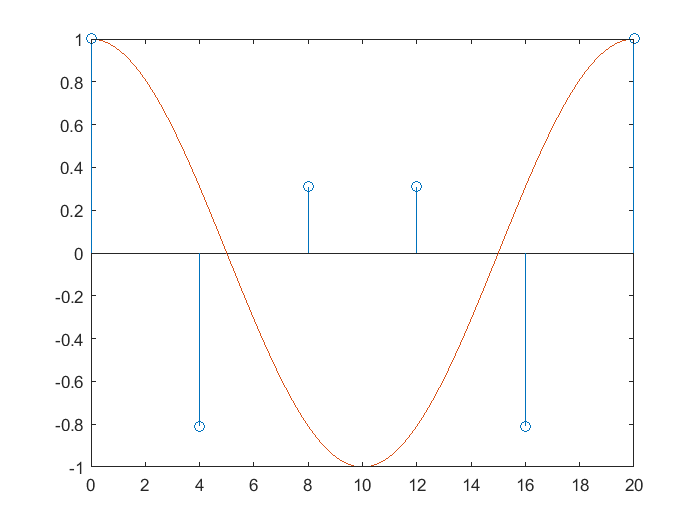

figure(4); %opens a new figure with handle#3
f1 = 0.1; %.1 Hz frequency for oversampled DT signal
f2 = 0.05; %.1 Hz frequency for "CT" signal
 %calculate the sampled DT signal
t1 = 0:4:20; %5 samples over 20 seconds
y1 = cos(2*pi*f1*t1);
%calculate the oversampled signal (CT)
t2 = 0:0.1:20; %200 samples over 20 seconds
y2 = cos(2*pi*f2*t2);
%compare DT to CT
stem(t1, y1);
hold on;
plot(t2, y2);
hold off;

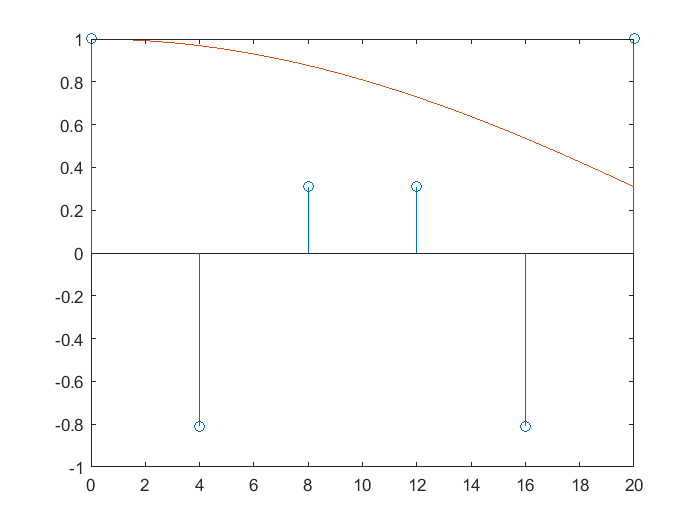

figure(5); %opens a new figure with handle#3
f1 = 0.1; %.1 Hz frequency for oversampled DT signal
f2 = 0.01; %.1 Hz frequency for "CT" signal
 %calculate the sampled DT signal
t1 = 0:4:20; %5 samples over 20 seconds
y1 = cos(2*pi*f1*t1);
%calculate the oversampled signal (CT)
t2 = 0:0.1:20; %200 samples over 20 seconds
y2 = cos(2*pi*f2*t2);
%compare DT to CT
stem(t1, y1);
hold on;
plot(t2, y2);
hold off;

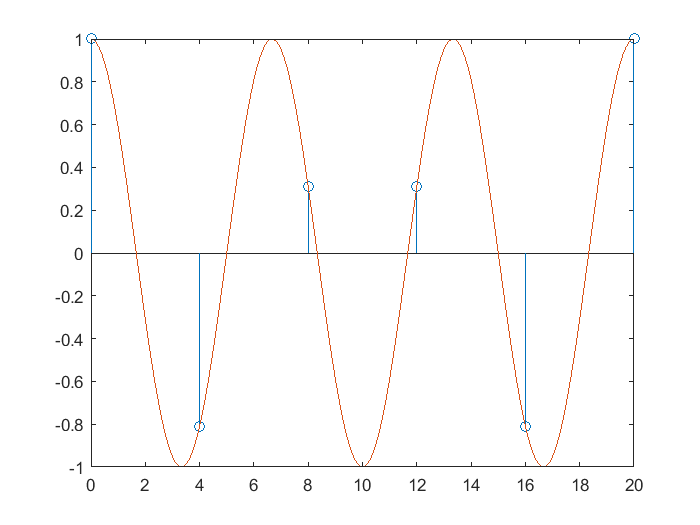

figure(6); %opens a new figure with handle#3
f1 = 0.1; %.1 Hz frequency for oversampled DT signal
f2 = 0.15; %.1 Hz frequency for "CT" signal
 %calculate the sampled DT signal
t1 = 0:4:20; %5 samples over 20 seconds
y1 = cos(2*pi*f1*t1);
%calculate the oversampled signal (CT)
t2 = 0:0.1:20; %200 samples over 20 seconds
y2 = cos(2*pi*f2*t2);
%compare DT to CT
stem(t1, y1);
hold on;
plot(t2, y2);
hold off;

## Lab Assignment: 

% Butterworth Filter
W1 = 12500 * 2 *pi;     % Lower bandpass limit
W2 = 15500 * 2*pi;      % Upper bandpass limit
Wn = [W1 W2];
[b1,a1] = butter(2,Wn,'bandpass','s')       % 4th Order Butterworth filter coefficients

b1 = 	1.0e+08 *

         0         0    3.5531         0         0


a1 = 	1.0e+19 *

    0.0000    0.0000    0.0000    0.0000    5.8506


tf(b1,a1)               % obtaining butterworth filter transfer function 

ans =
 
                        3.553e08 s^2
  ---------------------------------------------------------
  s^4 + 2.666e04 s^3 + 1.565e10 s^2 + 2.039e14 s + 5.851e19
 
Continuous-time transfer function.



w = (0):(2*pi*10):(2*pi*30000);       % Frequency Range Vector
ButterFunc = (3.55e08 * (i.*w).^2) ./ ((i.*w).^4 + 2.66e04*(i.*w).^3 + 1.565e10*(i.*w).^2 + 2.039e14*(i.*w) + 5.851e19) % replace s with jw for v/v function

ButterFunc =    0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i


plot(w,ButterFunc)      % Plotting V/V transfer function

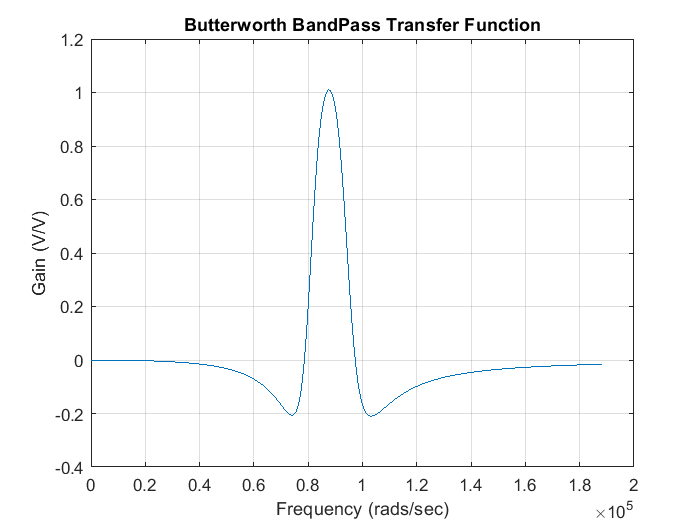

grid;
xlabel('Frequency (rads/sec)')
ylabel('Gain (V/V)')
title ('Butterworth BandPass Transfer Function')


% Db Plot

dB_ButterFunc = 20*log(abs(ButterFunc))% converting units to dB

dB_ButterFunc =       -Inf -350.9435 -323.2176 -306.9989 -295.4914 -286.5655 -279.2724 -273.1061 -267.7646 -263.0529 -258.8381 -255.0252 -251.5443 -248.3421 -245.3772 -242.6169 -240.0347 -237.6090 -235.3220 -233.1585 -231.1060 -229.1535 -227.2918 -225.5128 -223.8095 -222.1756 -220.6057 -219.0950 -217.6392 -216.2343 -214.8771 -213.5642 -212.2930 -211.0607 -209.8652 -208.7043 -207.5760 -206.4786 -205.4103 -204.3697 -203.3553 -202.3659 -201.4003 -200.4573 -199.5360 -198.6352 -197.7542 -196.8920 -196.0479 -195.2211


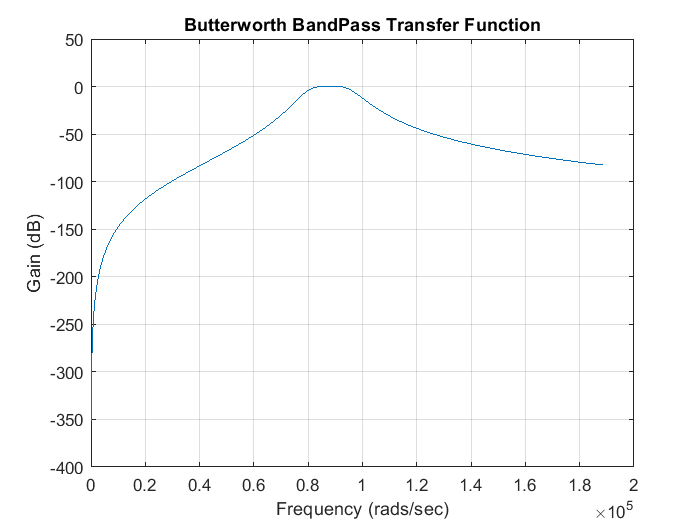

plot(w,dB_ButterFunc)       % Plotting dB Gain Transfer Function
grid;
xlabel('Frequency (rads/sec)')
ylabel('Gain (dB)')
title ('Butterworth BandPass Transfer Function')

% Cheby1 
[b2,a2] = cheby1(2,2,Wn,'bandpass','s');  % 4th Order cheby1 filter coefficients
tf(b2,a2)           % obtaining cheby1 filter transfer function

ans =
 
                        2.323e08 s^2
  ---------------------------------------------------------
  s^4 + 1.515e04 s^3 + 1.559e10 s^2 + 1.159e14 s + 5.851e19
 
Continuous-time transfer function.



Cheby1Func = (2.323e08*(i.*w).^2) ./ ((i.*w).^4 + 1.515e04*(i.*w).^3 + 1.559e10* (i.*w).^2 +1.159e14*(i.*w) +5.851e19)

Cheby1Func =    0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i


plot(w,Cheby1Func)  % Plotting V/V transfer function

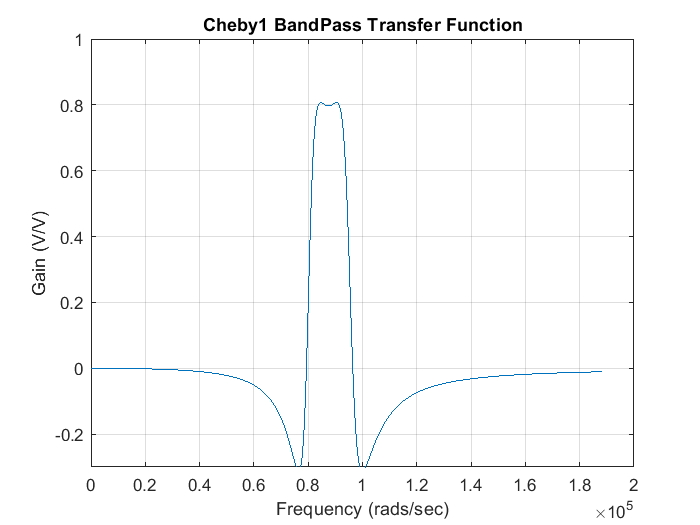

grid;
xlabel('Frequency (rads/sec)')
ylabel('Gain (V/V)')
title ('Cheby1 BandPass Transfer Function')
ylim([-0.3 1]);

% dB Plot

dB_Cheby1Func = 20*log(abs(Cheby1Func))% converting units to dB

dB_Cheby1Func =       -Inf -359.4253 -331.6993 -315.4806 -303.9732 -295.0473 -287.7542 -281.5879 -276.2463 -271.5346 -267.3198 -263.5070 -260.0260 -256.8238 -253.8589 -251.0986 -248.5164 -246.0907 -243.8037 -241.6402 -239.5877 -237.6352 -235.7735 -233.9945 -232.2911 -230.6572 -229.0873 -227.5766 -226.1207 -224.7159 -223.3586 -222.0457 -220.7745 -219.5422 -218.3467 -217.1858 -216.0575 -214.9600 -213.8917 -212.8511 -211.8367 -210.8473 -209.8817 -208.9387 -208.0173 -207.1165 -206.2354 -205.3732 -204.5291 -203.7023


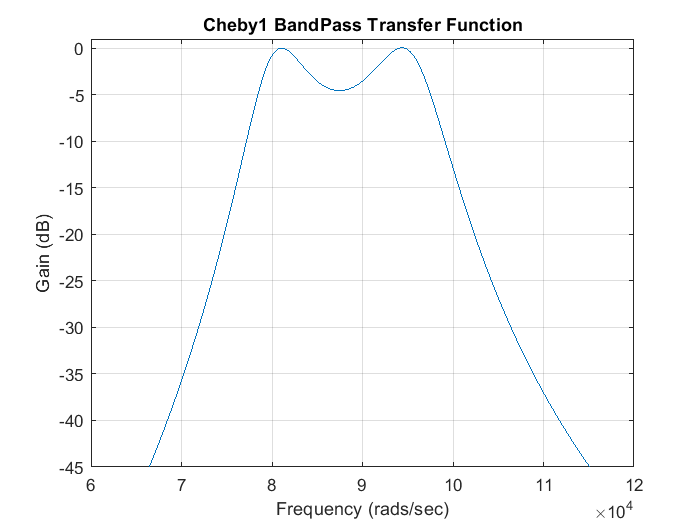

plot(w,dB_Cheby1Func)       % Plotting dB Gain Transfer Function
grid;
xlabel('Frequency (rads/sec)')
ylabel('Gain (dB)')
title ('Cheby1 BandPass Transfer Function')
ylim([-45 1]);

% Cheby2
[b3,a3] = cheby2(2,2,Wn,'bandpass','s');   % 4th Order cheby2 filter coefficients
tf(b3,a3)       % obtaining cheby2 filter transfer function

ans =
 
            0.7943 s^4 + 1.272e10 s^2 + 4.647e19
  ---------------------------------------------------------
  s^4 + 1.524e04 s^3 + 1.586e10 s^2 + 1.166e14 s + 5.851e19
 
Continuous-time transfer function.



Cheby2Func = (0.7943*(i.*w).^4  + 1.272e10*(i.*w).^2 + 4.647e19) ./ ((i.*w).^4 + 1.524e04*(i.*w).^3 + 1.586e10*(i.*w).^2 +1.166e14*(i.*w) +5.851e19)

Cheby2Func =    0.7942 + 0.0000i   0.7942 - 0.0001i   0.7942 - 0.0002i   0.7942 - 0.0003i   0.7942 - 0.0004i   0.7942 - 0.0005i   0.7942 - 0.0006i   0.7942 - 0.0007i   0.7942 - 0.0008i   0.7942 - 0.0009i   0.7942 - 0.0010i   0.7942 - 0.0011i   0.7942 - 0.0012i   0.7942 - 0.0013i   0.7942 - 0.0014i   0.7942 - 0.0015i   0.7942 - 0.0016i   0.7942 - 0.0017i   0.7942 - 0.0018i   0.7942 - 0.0019i   0.7942 - 0.0020i   0.7942 - 0.0021i   0.7942 - 0.0022i   0.7942 - 0.0023i   0.7942 - 0.0024i   0.7942 - 0.0025i   0.7942 - 0.0026i   0.7942 - 0.0027i   0.7942 - 0.0028i   0.7942 - 0.0029i   0.7942 - 0.0030i   0.7942 - 0.0031i   0.7942 - 0.0032i   0.7942 - 0.0033i   0.7942 - 0.0034i   0.7942 - 0.0035i   0.7942 - 0.0036i   0.7942 - 0.0037i   0.7942 - 0.0038i   0.7942 - 0.0039i   0.7942 - 0.0040i   0.7942 - 0.0041i   0.7942 - 0.0042i   0.7942 - 0.0043i   0.7942 - 0.0044i   0.7942 - 0.0045i   0.7942 - 0.0046i   0.7942 - 0.0047i   0.7942 - 0.0048i   0.7942 - 0.0049i


plot(w,Cheby2Func)  % Plotting V/V transfer function

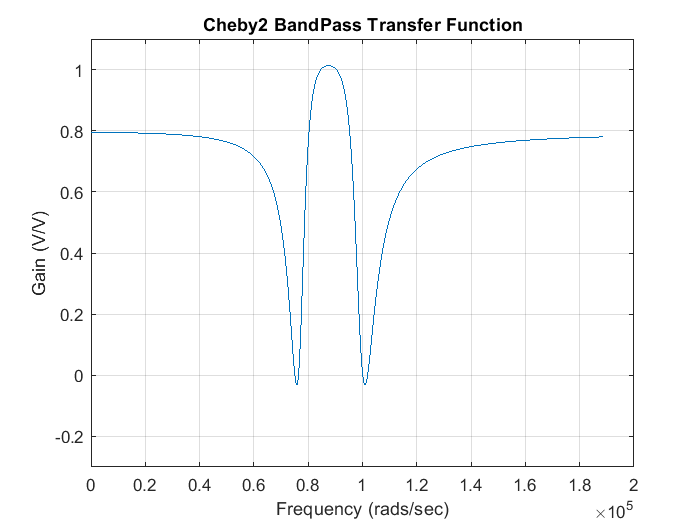

grid;
xlabel('Frequency (rads/sec)')
ylabel('Gain (V/V)')
title ('Cheby2 BandPass Transfer Function')
ylim([-0.3 1.1])

%dB Plot

dB_Cheby2Func = 20*log(abs(Cheby2Func))% converting units to dB

dB_Cheby2Func =    -4.6078   -4.6078   -4.6078   -4.6078   -4.6078   -4.6078   -4.6078   -4.6078   -4.6078   -4.6078   -4.6079   -4.6079   -4.6079   -4.6079   -4.6079   -4.6079   -4.6079   -4.6079   -4.6079   -4.6079   -4.6080   -4.6080   -4.6080   -4.6080   -4.6080   -4.6080   -4.6081   -4.6081   -4.6081   -4.6081   -4.6081   -4.6082   -4.6082   -4.6082   -4.6082   -4.6083   -4.6083   -4.6083   -4.6083   -4.6084   -4.6084   -4.6084   -4.6085   -4.6085   -4.6085   -4.6086   -4.6086   -4.6086   -4.6087   -4.6087


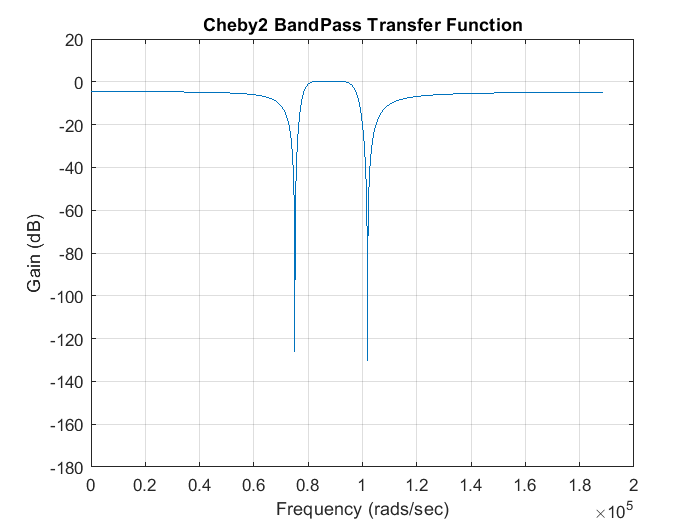

plot(w,dB_Cheby2Func)       % Plotting dB Gain Transfer Function
grid;
xlabel('Frequency (rads/sec)')
ylabel('Gain (dB)')
title ('Cheby2 BandPass Transfer Function')
ylim([-180 20])

[b4,a4] = ellip(2,2,30,Wn,'bandpass','s');    % 4th Order Ellip filter coefficients
tf(b4,a4)       % obtaining ellip filter transfer function

ans =
 
            0.03162 s^4 + 7.216e08 s^2 + 1.85e18
  --------------------------------------------------------
  s^4 + 1.484e04 s^3 + 1.56e10 s^2 + 1.135e14 s + 5.851e19
 
Continuous-time transfer function.



EllipFunc = (0.03162*(i.*w).^4 + 7.216e08*(i.*w).^2 + 1.85e18) ./ ((i.*w).^4 + 1.484e04*(i.*w).^3 + 1.56e10*(i.*w).^2 +1.135e14*(i.*w) +5.851e19)

EllipFunc =    0.0316 + 0.0000i   0.0316 - 0.0000i   0.0316 - 0.0000i   0.0316 - 0.0000i   0.0316 - 0.0000i   0.0316 - 0.0000i   0.0316 - 0.0000i   0.0316 - 0.0000i   0.0316 - 0.0000i   0.0316 - 0.0000i   0.0316 - 0.0000i   0.0316 - 0.0000i   0.0316 - 0.0000i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0001i   0.0316 - 0.0002i   0.0316 - 0.0002i   0.0316 - 0.0002i   0.0316 - 0.0002i   0.0316 - 0.0002i   0.0316 - 0.0002i   0.0316 - 0.0002i   0.0316 - 0.0002i   0.0316 - 0.0002i   0.0316 - 0.0002i   0.0316 - 0.0002i


figure;
plot(w,EllipFunc)   % Plotting V/V transfer function

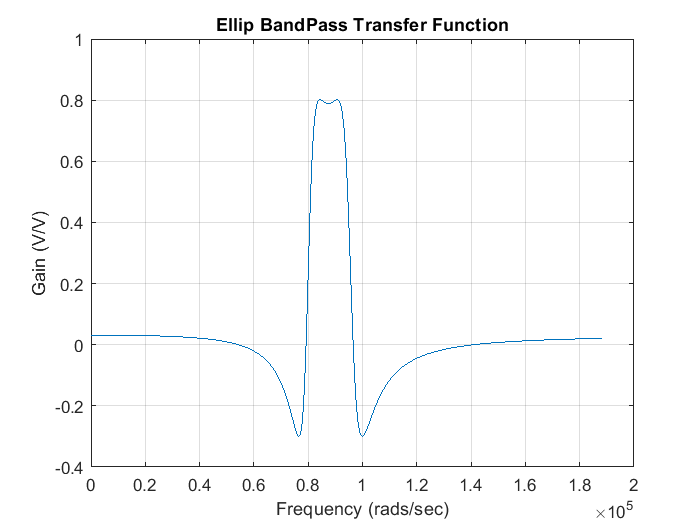

grid;
xlabel('Frequency (rads/sec)')
ylabel('Gain (V/V)')
title ('Ellip BandPass Transfer Function')


%dB Plot

dB_EllipFunc = 20*log(abs(EllipFunc))   % converting units to dB

dB_EllipFunc =   -69.0802  -69.0803  -69.0803  -69.0803  -69.0804  -69.0805  -69.0806  -69.0807  -69.0809  -69.0810  -69.0812  -69.0814  -69.0817  -69.0819  -69.0822  -69.0825  -69.0828  -69.0831  -69.0834  -69.0838  -69.0842  -69.0846  -69.0850  -69.0855  -69.0859  -69.0864  -69.0869  -69.0875  -69.0880  -69.0886  -69.0892  -69.0898  -69.0904  -69.0910  -69.0917  -69.0924  -69.0931  -69.0938  -69.0946  -69.0953  -69.0961  -69.0969  -69.0977  -69.0986  -69.0994  -69.1003  -69.1012  -69.1022  -69.1031  -69.1041


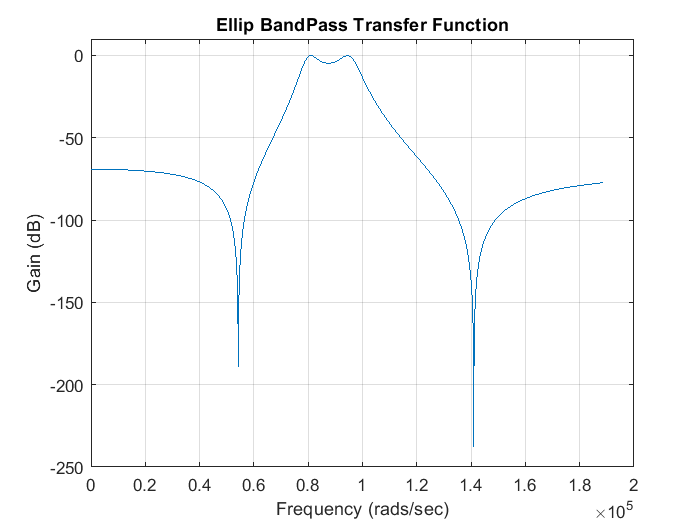

plot(w,dB_EllipFunc)       % Plotting dB Gain Transfer Function
grid;
xlabel('Frequency (rads/sec)')
ylabel('Gain (dB)')
title ('Ellip BandPass Transfer Function')
ylim([-250 10])

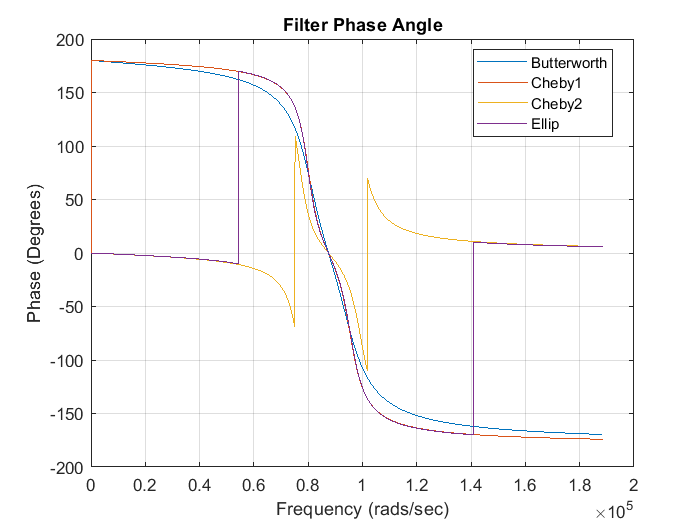

% Freqs
ButterFreq = freqs(b1,a1,w);
Mag_ButterFreq = abs(ButterFreq);   % Magnitude of the Transfer function
Phase_ButterFreq = angle(ButterFreq) * (180/pi);     % Phase Angle of the Transfer Function

Cheby1Freq = freqs(b2,a2,w);
Mag_Cheby1Freq = abs(Cheby1Freq);   % Magnitude of the Transfer function
Phase_Cheby1Freq = angle(Cheby1Freq) * (180/pi);    % Phase Angle of the Transfer Function

Cheby2Freq = freqs(b3,a3,w);
Mag_Cheby2Freq = abs(Cheby2Freq);   % Magnitude of the Transfer function
Phase_Cheby2Freq = angle(Cheby2Freq) * (180/pi);     % Phase Angle of the Transfer Function

EllipFreq = freqs(b4,a4,w);
Mag_EllipFreq = abs(EllipFreq);     % Magnitude of the Transfer function
Phase_EllipFreq = angle(EllipFreq) * (180/pi);       % Phase Angle of the Transfer Function

plot(w,Phase_ButterFreq,w,Phase_Cheby1Freq,w,Phase_Cheby2Freq,w, Phase_EllipFreq)   % Plotting all filter magnitudes
grid;
xlabel('Frequency (rads/sec)')
ylabel('Phase (Degrees)')
title ('Filter Phase Angle')
legend('Butterworth','Cheby1','Cheby2','Ellip','location',"best")



%plot(w,Mag_ButterFreq,w,Mag_Cheby1Freq,w,Mag_Cheby2Freq,w, Mag_EllipFreq)           % Plotting all filter phase angles
%grid;
%xlabel('Frequency (rads/sec)')
%ylabel('Gain (V/V)')
%title ('Filter Transfer Function Magnitude')
%legend('Butterworth','Cheby1','Cheby2','Ellip','location',"best")
%ylim([-0.1 1.1])


plot(w,ButterFreq,w,Cheby1Freq,w,Cheby2Freq,w, EllipFreq)           % Plotting all filter phase angles

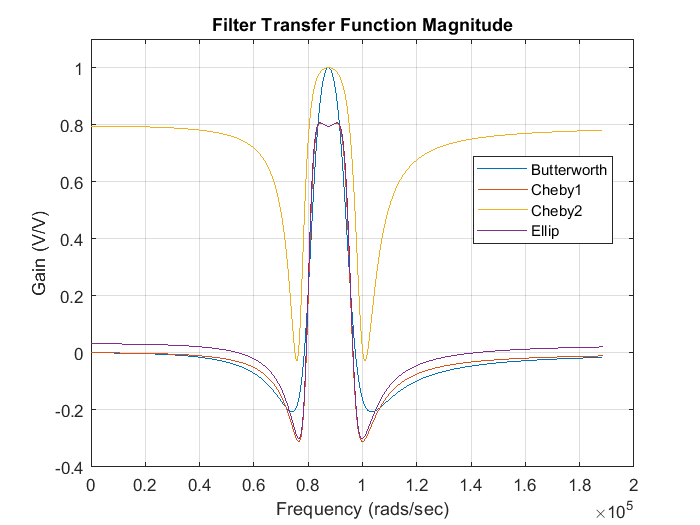

grid;
xlabel('Frequency (rads/sec)')
ylabel('Gain (V/V)')
title ('Filter Transfer Function Magnitude')
legend('Butterworth','Cheby1','Cheby2','Ellip','location',"best")
ylim([-0.4 1.1])